# Problem 8 Hedonic Pricing Model

## Reading Data

source_dir='D:\OneDrive - Columbia University\2016Fall\5. LINEAR REGRESSION MODELS\HW\hw4\Housing.csv';
opts=detectImportOptions(source_dir);
opts=setvartype(opts,[7:11,13],'categorical');
[opts.VariableNames;opts.VariableTypes]

ans =     'Var1'    'price'     'lotsize'    'bedrooms'    'bathrms'    'stories'    'driveway'       'recroom'        'fullbase'       'gashw'          'airco'          'garagepl'    'prefarea'   
    'char'    'double'    'double'     'double'      'double'     'double'     'categorical'    'categorical'    'categorical'    'categorical'    'categorical'    'double'      'categorical'


data=readtable(source_dir,opts);

## Part A

1. Calculate the average price of apartments that have 1, 2, 3, 4, 5 bedrooms respectively.

price_by_bedrs =grpstats(data,'bedrooms','mean','DataVars','price')

price_by_bedrs =          bedrooms    GroupCount    mean_price
         ________    __________    __________

    1    1             2           38750     
    2    2           136           51886     
    3    3           301           70817     
    4    4            95           81854     
    5    5            10           83140     
    6    6             2           68450     


2. Plot these averages in terms of the number of bedrooms.

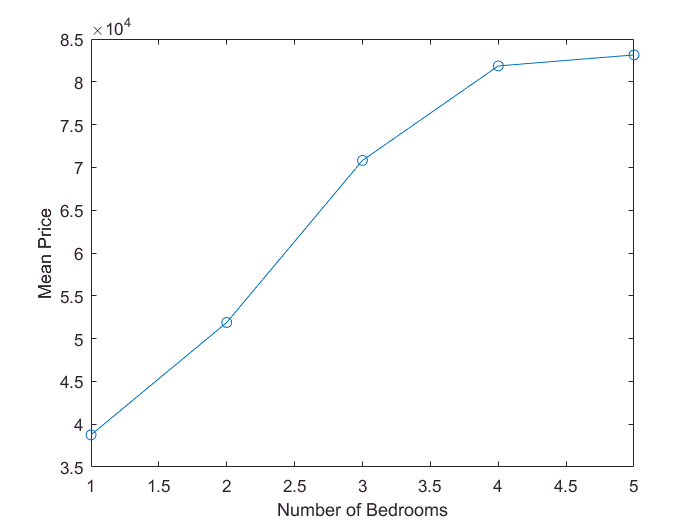

filter=price_by_bedrs.bedrooms<=5;
figure
plot(price_by_bedrs.bedrooms(filter),price_by_bedrs.mean_price(filter),'-o')
xlabel('Number of Bedrooms');
ylabel('Mean Price');

3. Use OLS to fit a line to this graph.   

md1 = fitlm(price_by_bedrs,'mean_price ~ bedrooms','Exclude',6)

md1 = 
Linear regression model:
    mean_price ~ 1 + bedrooms

Estimated Coefficients:
                   Estimate      SE      tStat      pValue 
                   ________    ______    ______    ________

    (Intercept)    29665       5978.1    4.9623    0.015715
    bedrooms       11875       1802.5    6.5881    0.007117


Number of observations: 5, Error degrees of freedom: 3
Root Mean Squared Error: 5.7e+03
R-squared: 0.935,  Adjusted R-Squared 0.914
F-statistic vs. constant model: 43.4, p-value = 0.00712

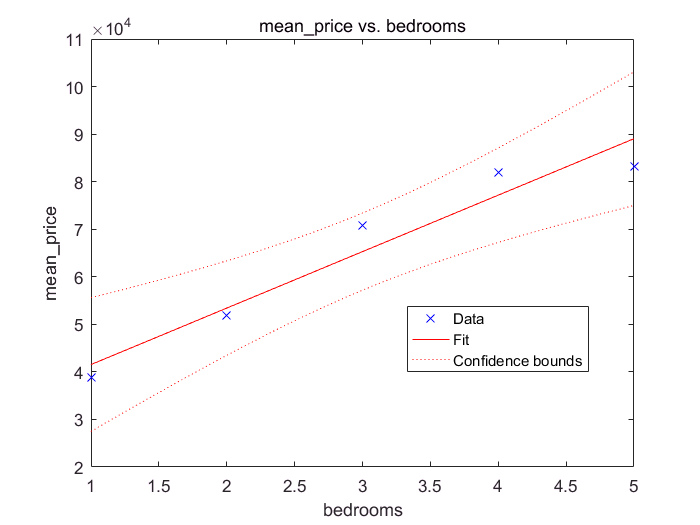

plot(md1)

**Question: Given this model, how much does the price on average increase for an extra bedroom?**

Answer: Given this model, the price increases 11,875 on average for an extra bedroom.

**Question: Do you think that the loss function that OLS uses is good for this model?**

**Answer:**

The loss function is


$$\sum_{i=1}^{5} {\left({mean_price}_i −\text{  }\beta {\text{ }}_0 +\beta {\text{ }}_1 \cdot {bedrooms}_i \right)}^2$$


It is good for this model considering the three assumptions of OLS from the theoretical point of view. By minimizing the loss, we get very good results from the practice point of view. 

## Part B

**Claim:** The higher price of the apartments with more bedrooms is because of the fact that houses with more bedrooms have larger lot-sizes and the increase you see in the price is because of larger lot-size and not more bedrooms. 

Can you do some regression analysis to see if my claim is true or not? 

I now include on more term, namlely mean_lotsize in my model.

filter=data.bedrooms<=5;
gp2=grpstats(data(filter,:),'bedrooms','mean','DataVars',{'price','lotsize'})

gp2 =          bedrooms    GroupCount    mean_price    mean_lotsize
         ________    __________    __________    ____________

    1    1             2           38750           3710      
    2    2           136           51886         4636.2      
    3    3           301           70817         5225.9      
    4    4            95           81854         5582.1      
    5    5            10           83140         6291.5      


md2 = fitlm(gp2,'mean_price~mean_lotsize+bedrooms')

md2 = 
Linear regression model:
    mean_price ~ 1 + bedrooms + mean_lotsize

Estimated Coefficients:
                    Estimate      SE       tStat     pValue 
                    ________    ______    _______    _______

    (Intercept)       9401       78070    0.12042    0.91516
    bedrooms        8073.4       14743     0.5476    0.63891
    mean_lotsize    6.2227      23.872    0.26067    0.81873


Number of observations: 5, Error degrees of freedom: 2
Root Mean Squared Error: 6.87e+03
R-squared: 0.937,  Adjusted R-Squared 0.875
F-statistic vs. constant model: 15, p-value = 0.0625

**Question:** **What is the conclusion?**

**Conclusion: The claim is not true.** Because the coefficient for bedrooms is much greater than that for mean_lotsize in the model $mean\text{ }price~mean\text{ }lotsize+bedrooms$ 

## Part C

I claim that apartments with fully furnished basements have higher prices. 

**Question:** Can you check whether this claim is true or not? How do you check it?

**Answer:** I simply calculate the mean and median price of apartments grouped by wether they have  fully furnished basements or not.

**Conclusion: **From the results below, the claim is true.

grpstats(data,'fullbase',{'mean','median'},'DataVars','price')

ans =            fullbase    GroupCount    mean_price    median_price
           ________    __________    __________    ____________

    no     no          355           64478         58500       
    yes    yes         191           74895         70000       


## **Part D**

- Plot the price of the apartments in terms of their lot-sizes for the apartments which have 2 bedrooms and 1 bathroom.

- Fit a line to predict the price of these apartments from their lot-size.

filter=data.bedrooms==2&data.bathrms==1;
sample1=data(filter,:);
md3=fitlm(sample1,'price~lotsize')

md3 = 
Linear regression model:
    price ~ 1 + lotsize

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)     32511       2621.4    12.402     1.407e-23
    lotsize        4.0411      0.51721    7.8133    1.8956e-12


Number of observations: 128, Error degrees of freedom: 126
Root Mean Squared Error: 1.15e+04
R-squared: 0.326,  Adjusted R-Squared 0.321
F-statistic vs. constant model: 61, p-value = 1.9e-12

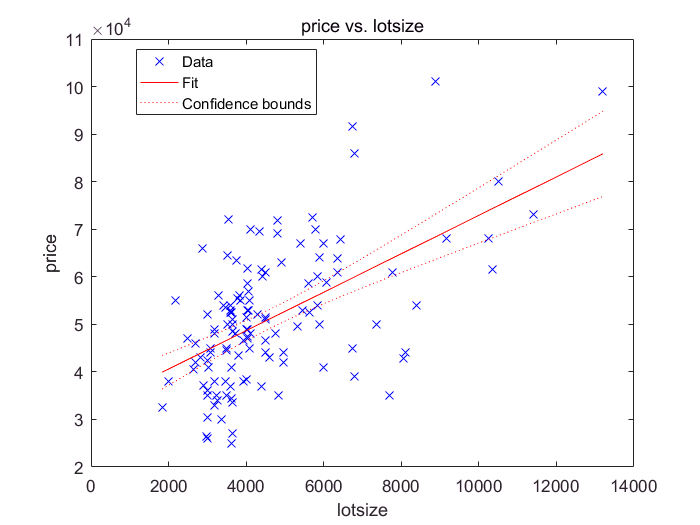

figure
plot(md3)

## Part E

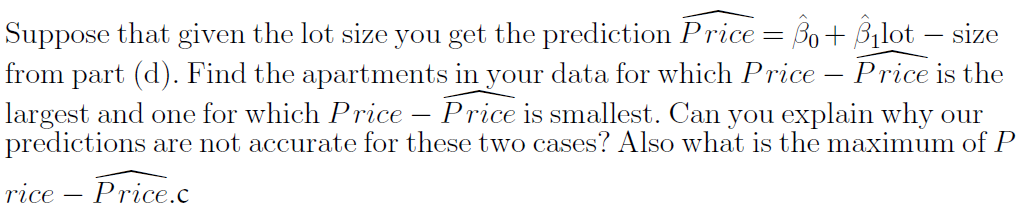

error=md3.Residuals.Raw;
[maximum_residual,i]=max(error);
maximum_residual,sample1(i,:)

maximum_residual = 3.2605e+04

ans =     Var1      price      lotsize    bedrooms    bathrms    stories    driveway    recroom    fullbase    gashw    airco    garagepl    prefarea
    _____    ________    _______    ________    _______    _______    ________    _______    ________    _____    _____    ________    ________

    '327'    1.01e+05    8880       2           1          1          yes         no         no          no       yes      1           no      


[most_negative_residual,i]=min(error);
most_negative_residual,sample1(i,:)

most_negative_residual = -2.8627e+04

ans =     Var1     price    lotsize    bedrooms    bathrms    stories    driveway    recroom    fullbase    gashw    airco    garagepl    prefarea
    _____    _____    _______    ________    _______    _______    ________    _______    ________    _____    _____    ________    ________

    '138'    35000    7700       2           1          1          yes         no         no          no       no       0           no      


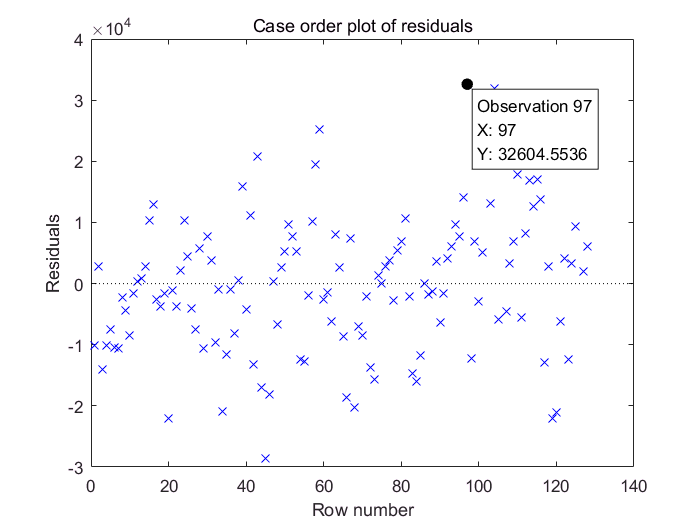

plotResiduals(md3,'caseorder')

**Answer: **

The reason that our prediction is not accurate for the first case is that this apartment **has central air conditioning and 1 garage place.**

While the second apartment has no such amenities. The maximum residual is **32,605**

## Part F

Consider the full linear model we considered in the class and make predictions on the price of apartments. 

terms=strcat('+',data.Properties.VariableNames(3:end));
terms=strcat('1',terms{:});
form=['price ~ ',terms];
md4=fitlm(data,form)

md4 = 
Linear regression model:
    price ~ 1 + lotsize + bedrooms + bathrms + stories + driveway + recroom + fullbase + gashw + airco + garagepl + prefarea

Estimated Coefficients:
                    Estimate      SE       tStat       pValue  
                    ________    ______    _______    __________

    (Intercept)     -4038.4     3409.5    -1.1845       0.23676
    lotsize          3.5463     0.3503     10.124    3.7324e-22
    bedrooms           1832       1047     1.7498      0.080733
    bathrms           14336     1489.9     9.6217    2.5704e-20
    stories          6556.9     925.29     7.0864     4.374e-12
    driveway_yes     6687.8     2045.2     3.2699     0.0011452
    recroom_yes      4511.3       1900     2.3744      0.017929
    fullbase_yes     5452.4       1588     3.4334    0.00064224
    gashw_yes         12831     3217.6     3.9879    7.5956e-05
    airco_yes         12633       1555     8.1239    3.1507e-15
    garagepl         4244.8     840.54     5.0501

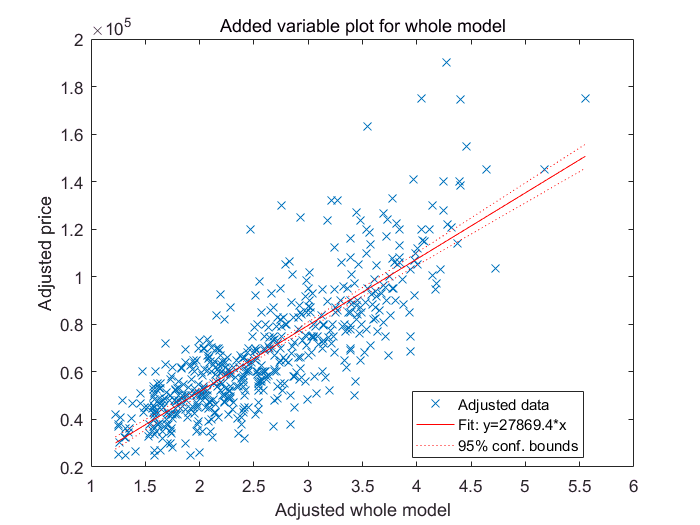

plot(md4)

For which 2 bedroom,1 bathroom apartment $Price−\hat{Price}$ is largest?

filter=data.bedrooms==2&data.bathrms==1;
sample2=data(filter,:);
error2=sample2.price-predict(md4,sample2);
[largest_residual,i]=max(error2);
largest_residual,sample2(i,:)

largest_residual = 2.8964e+04

ans =     Var1     price    lotsize    bedrooms    bathrms    stories    driveway    recroom    fullbase    gashw    airco    garagepl    prefarea
    _____    _____    _______    ________    _______    _______    ________    _______    ________    _____    _____    ________    ________

    '209'    72000    3540       2           1          1          no          yes        yes         no       no       0           no      


**Question:** If you compare this difference with the one you got in Part E, is your full linear model better than what you had before for two bedroom one bathroom apartments?  If yes, did you expect it to be? If no, why do you think this is the case?

**Answer: **Yes, by only comparing the maximum residual for  2 bedroom,1 bathroom apartment. The full linear model has a smaller largest residual (28,964) than that (32,605) of the model in part E, and hence is a better model. I didn't expect it to be so before I get the results but it just turned out to be so.